# ATTENTION:

Concepts explored here are utilsed in the script `bh_explore_eigenaxis_DCM_derivation`

## Clear the Symbolic engine of any assumptions

clear all

And our symbolic engine should have no assumptions

assumptions

 
ans =
 
Empty sym: 1-by-0
 


Assume that we have a **passive rotation matrix C** which has the form

syms E_X   E_Y   E_Z                      real
syms K_21  K_22  K_23  K_31  K_32  K_33   real

assumeAlso(1 == E_X^2 + E_Y^2 + E_Z^2);

C      = [  E_X,   E_Y,   E_Z;
           K_21,  K_22,  K_23;
           K_31,  K_32,  K_33; ]

$$C = \left(\begin{array}{ccc} E_{X} & E_{Y} & E_{Z}\\ K_{21} & K_{22} & K_{23}\\ K_{31} & K_{32} & K_{33} \end{array}\right)$$

Compute the determinant:

det_C = det(C)    

$$det\_C = E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}$$

Enforce the UNIT determinant constraint for a rotation matrix that ***transforms one Right hand co-ordinate frame to another Right handed co-ordinate frame***

assumeAlso(1==det_C)  

Compute the inverse $C^{-1}$ and transpose $C^T$ and then  equate $C^T =C^{-1}$

inv_C   = inv(C)    

$$inv\_C = \left(\begin{array}{ccc} \frac{K_{22}\,K_{33}-K_{23}\,K_{32}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & -\frac{E_{Y}\,K_{33}-E_{Z}\,K_{32}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & \frac{E_{Y}\,K_{23}-E_{Z}\,K_{22}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}}\\ -\frac{K_{21}\,K_{33}-K_{23}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & \frac{E_{X}\,K_{33}-E_{Z}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & -\frac{E_{X}\,K_{23}-E_{Z}\,K_{21}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}}\\ \frac{K_{21}\,K_{32}-K_{22}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & -\frac{E_{X}\,K_{32}-E_{Y}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & \frac{E_{X}\,K_{22}-E_{Y}\,K_{21}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} \end{array}\right)$$

trans_C = C.'

$$trans\_C = \left(\begin{array}{ccc} E_{X} & K_{21} & K_{31}\\ E_{Y} & K_{22} & K_{32}\\ E_{Z} & K_{23} & K_{33} \end{array}\right)$$


EQ      = trans_C == inv_C

$$EQ = \left(\begin{array}{ccc} E_{X}=\frac{K_{22}\,K_{33}-K_{23}\,K_{32}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & K_{21}=-\frac{E_{Y}\,K_{33}-E_{Z}\,K_{32}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & K_{31}=\frac{E_{Y}\,K_{23}-E_{Z}\,K_{22}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}}\\ E_{Y}=-\frac{K_{21}\,K_{33}-K_{23}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & K_{22}=\frac{E_{X}\,K_{33}-E_{Z}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & K_{32}=-\frac{E_{X}\,K_{23}-E_{Z}\,K_{21}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}}\\ E_{Z}=\frac{K_{21}\,K_{32}-K_{22}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & K_{23}=-\frac{E_{X}\,K_{32}-E_{Y}\,K_{31}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} & K_{33}=\frac{E_{X}\,K_{22}-E_{Y}\,K_{21}}{E_{X}\,K_{22}\,K_{33}-E_{X}\,K_{23}\,K_{32}-E_{Y}\,K_{21}\,K_{33}+E_{Y}\,K_{23}\,K_{31}+E_{Z}\,K_{21}\,K_{32}-E_{Z}\,K_{22}\,K_{31}} \end{array}\right)$$

EQ      = simplify(EQ)

$$EQ = \left(\begin{array}{ccc} E_{X}+K_{23}\,K_{32}=K_{22}\,K_{33} & K_{21}+E_{Y}\,K_{33}=E_{Z}\,K_{32} & K_{31}+E_{Z}\,K_{22}=E_{Y}\,K_{23}\\ E_{Y}+K_{21}\,K_{33}=K_{23}\,K_{31} & K_{22}+E_{Z}\,K_{31}=E_{X}\,K_{33} & K_{32}+E_{X}\,K_{23}=E_{Z}\,K_{21}\\ E_{Z}+K_{22}\,K_{31}=K_{21}\,K_{32} & K_{23}+E_{X}\,K_{32}=E_{Y}\,K_{31} & K_{33}+E_{Y}\,K_{21}=E_{X}\,K_{22} \end{array}\right)$$

Extract the equivalent equations that do NOT have cross coupled terms $K_{\textrm{RS}} \ldotp K_{\textrm{QM}}$

my_EQ = EQ(:,2:3);
my_EQ = my_EQ(:)

$$my\_EQ = \left(\begin{array}{c} K_{21}+E_{Y}\,K_{33}=E_{Z}\,K_{32}\\ K_{22}+E_{Z}\,K_{31}=E_{X}\,K_{33}\\ K_{23}+E_{X}\,K_{32}=E_{Y}\,K_{31}\\ K_{31}+E_{Z}\,K_{22}=E_{Y}\,K_{23}\\ K_{32}+E_{X}\,K_{23}=E_{Z}\,K_{21}\\ K_{33}+E_{Y}\,K_{21}=E_{X}\,K_{22} \end{array}\right)$$

For those 6 equations, rewrite them in the form $A\ldotp x=b$

- where   $x^T =\left\lbrack \begin{array}{cccccc}
K_{21}  & K_{22}  & K_{23}  & K_{31}  & K_{32}  & K_{33} 
\end{array}\right\rbrack$

[A,b] = equationsToMatrix(my_EQ, [K_21  K_22  K_23  K_31  K_32  K_33])

$$A = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & -E_{Z} & E_{Y}\\ 0 & 1 & 0 & E_{Z} & 0 & -E_{X}\\ 0 & 0 & 1 & -E_{Y} & E_{X} & 0\\ 0 & E_{Z} & -E_{Y} & 1 & 0 & 0\\ -E_{Z} & 0 & E_{X} & 0 & 1 & 0\\ E_{Y} & -E_{X} & 0 & 0 & 0 & 1 \end{array}\right)$$

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

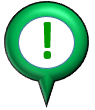**OBSERVATION: ** So it looks like we have an eigenvalue problem with an eigenvalue of $\lambda =-1$

- 
$$\left(A\right)\ldotp v=0$$


- 
$$\left(\hat{A} +I\right)\ldotp v=0$$


- $\left(\hat{A} \right)\ldotp v\;\;\;\;\;\;\;\;=\;\;\;-1\ldotp v$     where   $\hat{A} =A-I$

[eVec_mat, eVal_mat] = eig( A - eye(6) );

eVec_mat = simplify(eVec_mat)

$$eVec\_mat = \left(\begin{array}{cccccc} \frac{E_{X}}{E_{Z}} & 0 & E_{Z} & -E_{Y} & -E_{Z} & E_{Y}\\ \frac{E_{Y}}{E_{Z}} & 0 & \frac{E_{Y}\,E_{Z}}{E_{X}} & -\frac{{E_{Y}}^{2}-1}{E_{X}} & -\frac{E_{Y}\,E_{Z}}{E_{X}} & \frac{{E_{Y}}^{2}-1}{E_{X}}\\ 1 & 0 & \frac{{E_{Z}}^{2}-1}{E_{X}} & -\frac{E_{Y}\,E_{Z}}{E_{X}} & -\frac{{E_{Z}}^{2}-1}{E_{X}} & \frac{E_{Y}\,E_{Z}}{E_{X}}\\ 0 & \frac{E_{X}}{E_{Z}} & -\frac{E_{Y}}{E_{X}} & -\frac{E_{Z}}{E_{X}} & -\frac{E_{Y}}{E_{X}} & -\frac{E_{Z}}{E_{X}}\\ 0 & \frac{E_{Y}}{E_{Z}} & 1 & 0 & 1 & 0\\ 0 & 1 & 0 & 1 & 0 & 1 \end{array}\right)$$

eVal_mat = simplify(eVal_mat)

$$eVal\_mat = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

So columns 3 and 4 are the eigenvectors for $\lambda =-1$

### Consider Column 3:

tmp_vec = eVec_mat(:,3)

$$tmp\_vec = \left(\begin{array}{c} E_{Z}\\ \frac{E_{Y}\,E_{Z}}{E_{X}}\\ \frac{{E_{Z}}^{2}-1}{E_{X}}\\ -\frac{E_{Y}}{E_{X}}\\ 1\\ 0 \end{array}\right)$$

Enforce the nomalization (since the NORM of the ROWS of $C$must be 1)

% 1 = K_21^2 + K_22^2 + K_23^2
% 1 = K_31^2 + K_32^2 + K_33^2
tmp_n_vec = [  sqrt( dot(tmp_vec(1:3),tmp_vec(1:3))  );
               sqrt( dot(tmp_vec(1:3),tmp_vec(1:3))  );
               sqrt( dot(tmp_vec(1:3),tmp_vec(1:3))  );
               sqrt( dot(tmp_vec(4:6),tmp_vec(4:6))  );
               sqrt( dot(tmp_vec(4:6),tmp_vec(4:6))  );
               sqrt( dot(tmp_vec(4:6),tmp_vec(4:6))  );               
             ]

$$tmp\_n\_vec = \left(\begin{array}{c} \sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}\\ \sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}\\ \sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}\\ \sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1}\\ \sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1}\\ \sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1} \end{array}\right)$$

tmp_vec = tmp_vec ./ tmp_n_vec

$$tmp\_vec = \left(\begin{array}{c} \frac{E_{Z}}{\sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ \frac{E_{Y}\,E_{Z}}{E_{X}\,\sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ \frac{{E_{Z}}^{2}-1}{E_{X}\,\sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ -\frac{E_{Y}}{E_{X}\,\sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1}}\\ \frac{1}{\sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1}}\\ 0 \end{array}\right)$$

OK, so create

-  
$$C=\left\lbrack \begin{array}{ccc}
E_X  & E_Y  & E_Z \\
K_{21}  & K_{22}  & K_{23} \\
K_{31}  & K_{32}  & K_{33} 
\end{array}\right\rbrack$$


my_C = [  E_X,   E_Y,   E_Z;
         tmp_vec(1:3).'  ;
         tmp_vec(4:6).'  ;  ]

$$my\_C = \left(\begin{array}{ccc} E_{X} & E_{Y} & E_{Z}\\ \frac{E_{Z}}{\sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}} & \frac{E_{Y}\,E_{Z}}{E_{X}\,\sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}} & \frac{{E_{Z}}^{2}-1}{E_{X}\,\sqrt{\frac{{\left({E_{Z}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Z}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ -\frac{E_{Y}}{E_{X}\,\sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1}} & \frac{1}{\sqrt{\frac{{E_{Y}}^{2}}{{E_{X}}^{2}}+1}} & 0 \end{array}\right)$$

**Test it:**    Is  $I=C\;\ldotp C^T$

should_be_I = simplify(my_C * my_C.') 

$$should\_be\_I = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

**Test it:  **Are all of the COLUMN norms of $C$ unity ?

simplify(  [norm(my_C(:,1)),norm(my_C(:,2)),norm(my_C(:,3))]     )

$$ans = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$

**Test it:  **Are all of the ROW norms of $C$ unity ?

simplify(  [norm(my_C(1,:)),norm(my_C(2,:)),norm(my_C(3,:))]     )

$$ans = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$

Save this $C$ for later usage:

my_C3 = my_C;

### Consider Column 4:

tmp_vec = eVec_mat(:,4)

$$tmp\_vec = \left(\begin{array}{c} -E_{Y}\\ -\frac{{E_{Y}}^{2}-1}{E_{X}}\\ -\frac{E_{Y}\,E_{Z}}{E_{X}}\\ -\frac{E_{Z}}{E_{X}}\\ 0\\ 1 \end{array}\right)$$

Enforce the nomalization (since the NORM of the ROWS of $C$must be 1)

% 1 = K_21^2 + K_22^2 + K_23^2
% 1 = K_31^2 + K_32^2 + K_33^2
tmp_n_vec = [  sqrt( dot(tmp_vec(1:3),tmp_vec(1:3))  );
               sqrt( dot(tmp_vec(1:3),tmp_vec(1:3))  );
               sqrt( dot(tmp_vec(1:3),tmp_vec(1:3))  );
               sqrt( dot(tmp_vec(4:6),tmp_vec(4:6))  );
               sqrt( dot(tmp_vec(4:6),tmp_vec(4:6))  );
               sqrt( dot(tmp_vec(4:6),tmp_vec(4:6))  );               
             ]

$$tmp\_n\_vec = \left(\begin{array}{c} \sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}\\ \sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}\\ \sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}\\ \sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1}\\ \sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1}\\ \sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1} \end{array}\right)$$

tmp_vec = tmp_vec ./ tmp_n_vec

$$tmp\_vec = \left(\begin{array}{c} -\frac{E_{Y}}{\sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ -\frac{{E_{Y}}^{2}-1}{E_{X}\,\sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ -\frac{E_{Y}\,E_{Z}}{E_{X}\,\sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ -\frac{E_{Z}}{E_{X}\,\sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1}}\\ 0\\ \frac{1}{\sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1}} \end{array}\right)$$


my_C = [  E_X,   E_Y,   E_Z;
         tmp_vec(1:3).'  ;
         tmp_vec(4:6).'  ;  ]

$$my\_C = \left(\begin{array}{ccc} E_{X} & E_{Y} & E_{Z}\\ -\frac{E_{Y}}{\sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}} & -\frac{{E_{Y}}^{2}-1}{E_{X}\,\sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}} & -\frac{E_{Y}\,E_{Z}}{E_{X}\,\sqrt{\frac{{\left({E_{Y}}^{2}-1\right)}^{2}}{{E_{X}}^{2}}+{E_{Y}}^{2}+\frac{{E_{Y}}^{2}\,{E_{Z}}^{2}}{{E_{X}}^{2}}}}\\ -\frac{E_{Z}}{E_{X}\,\sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1}} & 0 & \frac{1}{\sqrt{\frac{{E_{Z}}^{2}}{{E_{X}}^{2}}+1}} \end{array}\right)$$

**Test it:**    Is  $I=C\;\ldotp C^T$

should_be_I = simplify(my_C * my_C.') 

$$should\_be\_I = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

**Test it:  **Are all of the COLUMN norms of $C$ unity ?

simplify(  [norm(my_C(:,1)),norm(my_C(:,2)),norm(my_C(:,3))]     )

$$ans = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$

**Test it:  **Are all of the ROW norms of $C$ unity ?

simplify(  [norm(my_C(1,:)),norm(my_C(2,:)),norm(my_C(3,:))]     )

$$ans = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$

Save this $C$ for later usage:

my_C4 = my_C;

## Note the following:

Although $C_3$ and $C_4$ are different, NOTE the following:

syms theta real

Add_R_Ad = [  1,            0,           0;
              0,   cos(theta),  sin(theta);
              0,  -sin(theta),  cos(theta); ]; 

- 
$$^{B}v = {^{B}R_{A}} \enspace . \enspace ^{A}v$$


- 
$$^{B}v \enspace = \enspace
\lbrack {^{B}R_{A''}} \enspace . \enspace
{^{A''}R_{A'}} \enspace . \enspace
{^{A'}R_{A}} \rbrack
\enspace . \enspace
{^A}v$$


- 
$$^{B}v \enspace = \enspace
\lbrack  [^{A'}R_A]^T \enspace . \enspace
{^{A''}R_{A'}} \enspace . \enspace
{^{A'}R_{A}} \rbrack
\enspace . \enspace
{^A}v$$


R3 =  my_C3.' * Add_R_Ad * my_C3 ; 
R4 =  my_C4.' * Add_R_Ad * my_C4 ; 


R3 = simplify(R3)

$$R3 = \left(\begin{array}{ccc} {E_{Y}}^{2}\,\cos\left(\theta \right)-{E_{Z}}^{2}-{E_{Y}}^{2}+{E_{Z}}^{2}\,\cos\left(\theta \right)+1 & E_{X}\,E_{Y}+\frac{E_{X}\,E_{Y}\,\cos\left(\theta \right)}{{E_{Z}}^{2}-1}+\frac{E_{Z}\,\sin\left(\theta \right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{Z}}^{2}-1}-\frac{E_{X}\,E_{Y}\,{E_{Z}}^{2}\,\cos\left(\theta \right)}{{E_{Z}}^{2}-1}+\frac{{E_{Y}}^{2}\,E_{Z}\,\sin\left(\theta \right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{X}}^{2}\,\left({E_{Z}}^{2}-1\right)} & E_{X}\,E_{Z}+\frac{\left(E_{Y}\,\sin\left(\theta \right)+E_{X}\,E_{Z}\,\cos\left(\theta \right)\right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{X}}^{2}}\\ E_{X}\,E_{Y}+\frac{E_{X}\,E_{Y}\,\cos\left(\theta \right)}{{E_{Z}}^{2}-1}-\frac{E_{Z}\,\sin\left(\theta \right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{Z}}^{2}-1}-\frac{E_{X}\,E_{Y}\,{E_{Z}}^{2}\,\cos\left(\theta \right)}{{E_{Z}}^{2}-1}-\frac{{E_{Y}}^{2}\,E_{Z}\,\sin\left(\theta \right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{X}}^{2}\,\left({E_{Z}}^{2}-1\right)} & \frac{{\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}^{2}\,\left(\cos\left(\theta \right)+{E_{Y}}^{2}-{E_{Y}}^{2}\,\cos\left(\theta \right)\right)}{{E_{X}}^{4}} & E_{Y}\,E_{Z}-\frac{\left(E_{X}\,\sin\left(\theta \right)-E_{Y}\,E_{Z}\,\cos\left(\theta \right)\right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{X}}^{2}}\\ E_{X}\,E_{Z}-E_{X}\,E_{Z}\,\cos\left(\theta \right)-\frac{E_{Y}\,\sin\left(\theta \right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{X}}^{2}} & E_{Y}\,E_{Z}+\frac{\sin\left(\theta \right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{E_{X}}-E_{Y}\,E_{Z}\,\cos\left(\theta \right) & {E_{Z}}^{2}+\frac{\cos\left(\theta \right)\,\left({E_{Z}}^{2}-1\right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right)}{{E_{X}}^{2}} \end{array}\right)$$

R4 = simplify(R4);

should_be_zero = simplify( (R3 - R4), "Steps", 100)

$$should\_be\_zero = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

OK, so what is $R$ ?

import bh_rots_PKG.bh_eul_eigenaxis_CLS

OBJ = bh_eul_eigenaxis_CLS([E_X; E_Y; E_Z], theta);

simplify(OBJ.DCM_B_given_A)

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right)+\left(\cos\left(\theta \right)-1\right)\,\left({E_{Y}}^{2}+{E_{Z}}^{2}-1\right) & E_{Z}\,\sin\left(\theta \right)-E_{X}\,E_{Y}\,\left(\cos\left(\theta \right)-1\right) & -E_{Y}\,\sin\left(\theta \right)-E_{X}\,E_{Z}\,\left(\cos\left(\theta \right)-1\right)\\ -E_{Z}\,\sin\left(\theta \right)-E_{X}\,E_{Y}\,\left(\cos\left(\theta \right)-1\right) & \cos\left(\theta \right)-{E_{Y}}^{2}\,\left(\cos\left(\theta \right)-1\right) & E_{X}\,\sin\left(\theta \right)-E_{Y}\,E_{Z}\,\left(\cos\left(\theta \right)-1\right)\\ E_{Y}\,\sin\left(\theta \right)-E_{X}\,E_{Z}\,\left(\cos\left(\theta \right)-1\right) & -E_{X}\,\sin\left(\theta \right)-E_{Y}\,E_{Z}\,\left(\cos\left(\theta \right)-1\right) & \cos\left(\theta \right)-{E_{Z}}^{2}\,\left(\cos\left(\theta \right)-1\right) \end{array}\right)$$


tmp_diff = simplify(R3 - OBJ.DCM_B_given_A)

$$tmp\_diff = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## And visualize $C_3$ and $C_4$

Pick an arbitrary UNIT vector:

tmp_e = [5,5,5]/norm([5,5,5]);

my_C3_doub = double( subs(my_C3,[E_X,E_Y,E_Z], tmp_e)  )

my_C3_doub =     0.5774    0.5774    0.5774
    0.4082    0.4082   -0.8165
   -0.7071    0.7071         0


my_C4_doub = double( subs(my_C4,[E_X,E_Y,E_Z], tmp_e)  )

my_C4_doub =     0.5774    0.5774    0.5774
   -0.4082    0.8165   -0.4082
   -0.7071         0    0.7071


Transform the unit vectors in the $B$-frame to their components in the $A$-frame

uB_for_3   = my_C3_doub.' * eye(3);
uB_for_4   = my_C4_doub.' * eye(3);


figure;
    plot3([0;uB_for_3(1,1)],[0;uB_for_3(2,1)],[0;uB_for_3(3,1)], '--r');  hold on
    plot3([0;uB_for_3(1,2)],[0;uB_for_3(2,2)],[0;uB_for_3(3,2)], '--g');  
    plot3([0;uB_for_3(1,3)],[0;uB_for_3(2,3)],[0;uB_for_3(3,3)], '--b');

    plot3([0;uB_for_4(1,1)],[0;uB_for_4(2,1)],[0;uB_for_4(3,1)], '-r');  
    plot3([0;uB_for_4(1,2)],[0;uB_for_4(2,2)],[0;uB_for_4(3,2)], '-g');  
    plot3([0;uB_for_4(1,3)],[0;uB_for_4(2,3)],[0;uB_for_4(3,3)], '-b');

Plot a "scaled" version of our $E$vector (scaled so we can also see the $X$-axes of the body frames)

plot3([0;tmp_e(1)]/2,[0;tmp_e(2)]/2,[0;tmp_e(3)]/2, '-m', "LineWidth",3);

grid("on");
xlabel("X"); ylabel("Y"); zlabel("Z"); 
xlim([-2,2]);  ylim([-2,2]);  zlim([-2,2]);
axis equal

And plot the $\textrm{XYZ}$ of the $A$-frame

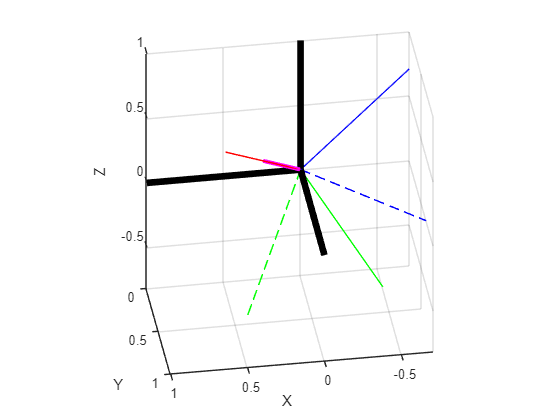

    plot3([0;1],[0;0],[0;0], '-k', "LineWidth",5);  
    plot3([0;0],[0;1],[0;0], '-k', "LineWidth",5);  
    plot3([0;0],[0;0],[0;1], '-k', "LineWidth",5);

view([-188.83 33.84])



my_C3_doub * tmp_e(:)

ans =      1
     0
     0



my_C4_doub * tmp_e(:)

ans =      1
     0
     0
